# Biomedical Robotics

# Group 1 - Assignment 3

## Matlab version

All models refers to Matlab/Simulink r2022b to be runned in the laboratory computer with the manipulator [Touch X](https://www.3dsystems.com/haptics-devices/touch-x).

## Model Initialization

Each Simulink model runs the following initialization function to declare the needed workspace variables:

- model sampling time *Ts*

- home coordinate (*coord_home*)

- reaching point vector (*coord_targets*)

clear all;

% fixed step time
Ts = 0.05;

% position threshold for reaching target / home center
th = 0.005;

% define home and target coordinates
n_target = 8;
radius = 0.1;
coord_home = [0,0];
% from requirements the targets are 8 along the circle of radius 10 cm
% equally spaced.
% The reaching action must be executed 10 times over the 8 targets randomly
% selected
coord_targets = zeros(n_target+2,2);
step = 2*pi/n_target;
for i=0:n_target-1
    coord_targets(i+1,:) = [radius*cos(i*step), radius*sin(i*step)];
end

% randomize coordiantes order
rand_idx = randi(n_target,[1,10]);
coord_targets = coord_targets(rand_idx,:);

## Reaching model

The model is based on the following state machine:

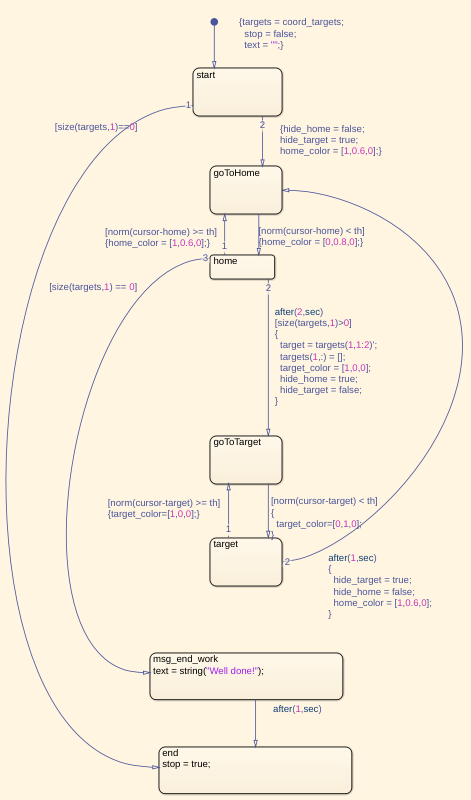

The main functionalities of the state machine are the followings:

- it acquires the list of targets to reach and store them in a local variable

- the home target appears and if the cursor stays for 2s within the home center position threshold, it disappears, the first target is extracted from the list and displayed in the virtual world.

- once the cursor reaches the target and stays for 1s within the target center position threshold, the target disappears and the home target appears again.

- the process repeats for all the reaching targets in the list

- once the list is empty, the simulation ends.

**To be noted:** for the laboratory code, the finishing text "Well done" in the virtual world, the *end* state was splitted in two states: one to display the string and one to end the model. The state transition between the two states takes 1 second to guarantee enough time for the string to be visualized in the virtual world

The reaching task is implemented in the following model:

open g1_reaching_2022b.slx

## Haptic Force Field

The haptic force field is composed by 4 components:

- a force with direction pointing from the starting point to the target point, with amplitude proportional to the distance between the target point and the end-effector. Such a force is named as *parallel*

- a force with direction ortogonal to the direction connecting the start point and the target point which drives the end-effector toward the ideal straight line from the start point to the target point. Such a force is activated if the end-effector is far from the ideal straight trajectory beyond a margin threshold. The amplitud is proportional to the distance between the end-effector position and the ideal straght line connecting the starting point and the target. Such a force is named as *orthogonal*

- a viscouse force with direction pointing from the starting point to the target point, with amplitude proportional to the end-effector velocity. Such a force is named as *parallel*,

- a force with direction ortogonal to the direction connecting the start point and the target point which drives the end-effector toward the ideal straight line from the start point to the target point. The amplitud is proportional to the velocity of the end-effector with direction orthogonal to the direction of the ideal straght line connecting the starting point and the target. Such a force is named as *orthogonal*

It is implemented in the following function:

%%
% Generates a force field to attract the manipulator end-effector to a goal
% position proportional to the distance and an anisotorpic viscousity,
% stronger on the orthogonal direction to the distance.
% If the end-effector position is outside a threshold with respect to the
% ideal linear trajectory, a resistive force  proportional with respect to 
% the distance from the ideal trajectory is applied to bring back the
% end-effector closer to the ideal trajectory.
% Home position is considered the origin at (0,0)
%
% NOTE:
% position in meter [m]
% velocity in meter/second [m/s]
%
% Notation:
%   p_ee = end-effector position (vector, 3x1)
%   v_ee = end-effector velocity (vector, 3x1)
%   p_g = goal position (vector, 3x1)
%   v_g = goal velocity (vector, 3x1)
%   a_pp = position error gain parallel (scalar)
%   a_po = position error gain orthogonal (scalar)
%   a_vp = viscosity gain parallel (scalar)
%   a_vo = viscosity gain orthogonal (scalar)
%   
%   p_margin = margin before apply direction compensation
%
% The attractive force is considered only on the plane, thus the following
% projector is considered:
%        
%   Rxy = [1 0 0;
%          0 1 0;
%          0 0 0]
%
% The coordinates will be projected in the plane using such an operator.
% Define distance frame with x-axis along the direction of the distance
% vector between the goal and home, y-axis orthogonal right-handed to it.
%
%   cos(theta) = p_g(1) / norm(p_g)
%   sin(theta) = p_g(2) / norm(p_g)
%
% Rotation matrix to move from world frame to distance frame:
%
%   dRw = [ cos(theta) sin(theta) 0
%          -sin(theta) cos(theta) 0
%                0          0     1]
%
% From now on it is considered to work in distance frame
% The attractive potential is defined as follows:
%
%   U_att = (1/2)*(p_g-p_ee)'*A_p*(p_g-p_ee) + (1/2)*(v_g-v_ee)'*A_v*(v_g-v_ee)
%
% so that the defined Uatt has a minimum at the goal position at zero velocity.
% The attractive force will be the opposite of the attractive potential
% gradient with respect to pee and vee, thus
%
%   F_att = - ∇p_ee(U_att) - ∇v_ee(U_att) = A_p(p_g - p_ee) + A_v(v_g - v_ee)
%
% By hypothesis the goal velocity v_g is null => v_g = 0.
% The resulting actractive force results as follows:
%
%   F_att = (A_p*(p_g-p_ee) - A_v*v_ee)
%
% Thresholds (p_th, v_th) are also considered, after which both
% the position and the velocity errors are considered small enough and the
% target reached.
% The found force needs to be converted into the world frame
%
%   wF_att = dRw'*F_att
%


#### NOTE: The following function is commented for convinience to keep exposition order, reporting the function before the model, which would break the live script, since the function definition should be always at the end of the live script

% function wF_att = forceField_aniso(enable, p_ee, v_ee, p_start, p_end, a_pp, a_po, a_vp, a_vo, p_th, v_th, p_margin)
% 
%     if enable
% 
%         % check if input vectors are rows. In case convert them to column
%         if isrow(p_ee)
%             p_ee = p_ee';
%         end
% 
%         if isrow(v_ee)
%             v_ee = v_ee';
%         end
% 
%         if isrow(p_start)
%             p_start = p_start';
%         end
% 
%         if isrow(p_end)
%             p_end = p_end';
%         end
% 
% 
%         % planar projector
%         Rxy = [1 0 0;
%                0 1 0;
%                0 0 0];
% 
%         % project goal and end-effector coordinates on the plane
%         p_end = Rxy*p_end;
%         p_ee = Rxy*p_ee;
%         v_ee = Rxy*v_ee;
% 
%         % planar rotation angle between world and distance frame:
%         cos_theta = (p_end(1) - p_start(1)) / norm(p_end - p_start);
%         sin_theta = (p_end(2) - p_start(2)) / norm(p_end - p_start);
% 
%         % rotation frame from world to distance frame
%         dRw = [ cos_theta sin_theta 0;
%                -sin_theta cos_theta 0;
%                     0         0     1];
% 
%         % move from world to distance frame
%         dp_end = dRw * p_end;
%         dp_ee = dRw * p_ee;
%         dv_ee = dRw * v_ee;
% 
%         % attractive force
%         wF_att = zeros(3,1);
% 
%         % position error matrix gain
%         A_p = zeros(3);
%         A_p(1,1) = a_pp;
%         % check if distance from ideal trajectory is greater than the margin
%         if (abs(dp_ee(2)) > p_margin)
%             A_p(2,2) = a_po;
%         end
% 
%         % viscous matrix gain
%         A_v = zeros(3);
%         A_v(1,1) = a_vp;
%         A_v(2,2) = a_vo;
% 
%         if (norm(Rxy*(dp_end - dp_ee)) > p_th) || (norm(Rxy*dv_ee) > v_th)
%             % errors greater than thresholds
%             wF_att = dRw' * (A_p*(dp_end - dp_ee) - A_v*(dv_ee));
%         end
% 
%     else % force field disabled
%         wF_att = [0,0,0]';
%     end
% end

## Force Field Model

The model is based on a state machine similar to the one used for the reaching task.

The main differences are the followings:

- output *enable_ff* to enable/disable the haptic force field. By default, the force field is disabled until the cursor reaches the first target is visualized.

- output *pos_start*/*pos_end*: used by the force field function to determine the direction between the starting and the end point, since the forces are applied both when the cursor have to move toward the target and when it has to move toward home position.

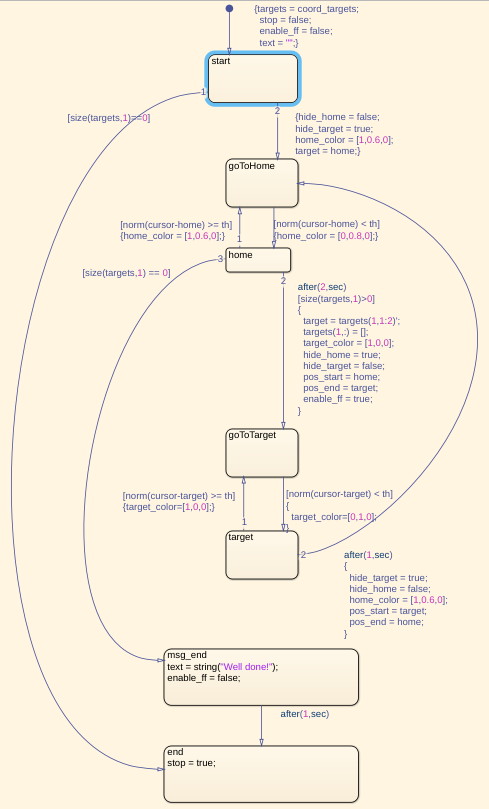

The force field task is implemented in the following model:

open g1_ForceField_spring_2022b.slx

## Viscose Force Field Model

The viscose force field model is the same as the one implemented for the simple force field, where the coeffcient for the viscose gain are specified, while the actractive gain are set to zero.

The viscose force field task is implemented in the follwoing model:

open g1_ForceField_spring_damper_2022b.slx

## Complete haptic force field

The force and the viscose fields are both considered setting all the gains, attractive and viscose ones, with the following values:

- attractive parallel gain: 2

- attractive orthogonal gain: 5

- viscose parallel gain: 10

- viscose orthogonal gain: 10